Start by measuring signal's similarity

Recover original and cleaned signals, with some additional information:

fs = 48000;
original = matfile('original_audio.mat');
recovered = matfile('recieved_audio.mat');
original_audio = original.audio_original;
recovered_audio = recovered.recieved_audio;
clear original;
clear recovered;

signal_path = 'data/second_waltz_reading_100_cm_volt_range_2.txt';
data_dec = readtable(signal_path, 'FileType', 'delimitedtext');
time = data_dec.Time;
clear data_dec;

Apply cross correlation and match the amplitudes:

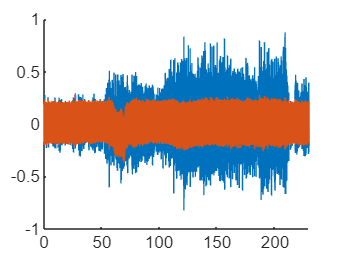

cc_mat = xcorr(original_audio, recovered_audio);
shift_options = cat(1, -flip(time(1: length(recovered_audio))), time(2: length(recovered_audio)));
% plot(shift_options, cc_mat');
max_cc = max(cc_mat);
shift_size = shift_options(cc_mat == max_cc);
clear cc_mat;
clear shift_options;
original_energy = max(xcorr(original_audio, original_audio));
recovered_energy = max(xcorr(recovered_audio, recovered_audio));
start_idx = find(time == abs(shift_size));
recovered_audio = recovered_audio(start_idx: end);
recovered_audio = recovered_audio - mean(recovered_audio);
original_audio = original_audio(1: end - start_idx + 1)';
original_audio = original_audio - mean(original_audio);
scaling_factor = original_energy / recovered_energy; % get recovered energy to the original energy
recovered_audio = recovered_audio * sqrt(scaling_factor); % sqrt to adjust the autocorrelation
N = length(recovered_audio);
time = time(1: N);
hold on;
plot(time, original_audio);
plot(time, recovered_audio);
hold off;

Now calculate the SNR and MSE:

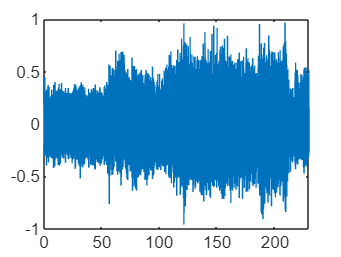

noise_signal = original_audio - recovered_audio;
plot(time, noise_signal)


% MSE
MSE = sum(noise_signal.^2) / N;

% SNR
P_signal = sum(original_audio.^2) / N;
SNR2 = 10 * log10(P_signal / MSE)

SNR2 = -3.0243

SNR = snr(original_audio, noise_signal);

% SSI
SSI = ssim(original_audio, recovered_audio)

SSI = 0.0154


% visqol (MOS)
MOS = visqol(recovered_audio, original_audio, fs)

MOS = 1.1887


% STOI
STOI = stoi(recovered_audio, original_audio, fs)

STOI = 0.3249